% Parameters
latitude = 13.7; % Observer's latitude in degrees
day_of_year = 172;   % Day of the year (e.g., 172 for June 21st)
time = linspace(6, 18, 100); % Time array (6 AM to 6 PM, 100 points)

% Solar Declination Angle (δ)
declination = 23.44 * sind(360/365 * (day_of_year - 81)); % in degrees

% Preallocate arrays for altitude, azimuth, and meridian angle
altitude = zeros(size(time));
azimuth = zeros(size(time));
ns_meridian_angle = zeros(size(time));

% Convert latitude and declination to radians
lat_rad = deg2rad(latitude);
decl_rad = deg2rad(declination);

% Loop over each time to calculate angles
for i = 1:length(time)
    % Solar time (T) in hours
    T = time(i);
    
    % Hour angle (H) in degrees
    H = 15 * (T - 12); % 15 degrees per hour, solar noon at 12
    
    % Convert H to radians
    H_rad = deg2rad(H);
    
    % Calculate Altitude Angle (θ₁)
    altitude(i) = asin(sin(decl_rad) * sin(lat_rad) + cos(decl_rad) * cos(lat_rad) * cos(H_rad));
    
    % Calculate Azimuth Angle (θ₂)
    azimuth(i) = atan2(-cos(decl_rad) * sin(H_rad), ...
        cos(lat_rad) * sin(decl_rad) - sin(lat_rad) * cos(decl_rad) * cos(H_rad));
    
    % Convert azimuth from radians to degrees, normalize to [0, 360]
    azimuth(i) = mod(rad2deg(azimuth(i)), 360);
    
    % Calculate North-South Meridian Angle
    if H <= 0
        % Morning: angle from North to zenith
        ns_meridian_angle(i) = 90 - rad2deg(altitude(i));
    else
        % Afternoon: angle from zenith to South
        ns_meridian_angle(i) = 90 + rad2deg(altitude(i));
    end
end% Loop over each time to calculate angles
for i = 1:length(time)
    % Solar time (T) in hours
    T = time(i);
    
    % Hour angle (H) in degrees
    H = 15 * (T - 12); % 15 degrees per hour, solar noon at 12
    
    % Convert H to radians
    H_rad = deg2rad(H);
    
    % Calculate Altitude Angle (θ₁)
    altitude(i) = asin(sin(decl_rad) * sin(lat_rad) + cos(decl_rad) * cos(lat_rad) * cos(H_rad));
    
    % Calculate Azimuth Angle (θ₂)
    azimuth(i) = atan2(-cos(decl_rad) * sin(H_rad), ...
        cos(lat_rad) * sin(decl_rad) - sin(lat_rad) * cos(decl_rad) * cos(H_rad));
    
    % Convert azimuth from radians to degrees, normalize to [0, 360]
    azimuth(i) = mod(rad2deg(azimuth(i)), 360);
    
    % Calculate North-South Meridian Angle
    % Zenith = 0, North Horizon = -90, South Horizon = +90
    ns_meridian_angle(i) = rad2deg(altitude(i)) - 90;
end

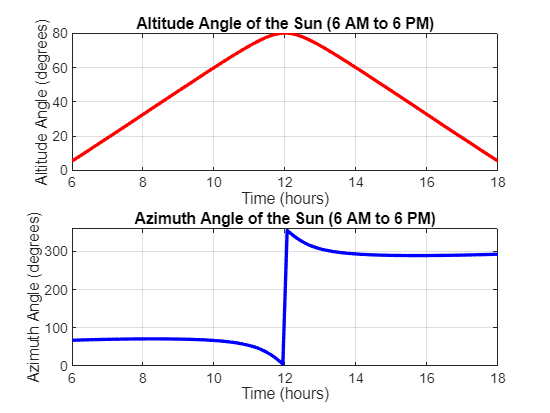

% Convert altitude to degrees
altitude_deg = rad2deg(altitude);

% Plot Azimuth and Altitude
figure;
subplot(2,1,1);
plot(time, altitude_deg, 'r', 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Altitude Angle (degrees)');
title('Altitude Angle of the Sun (6 AM to 6 PM)');
grid on;

subplot(2,1,2);
plot(time, azimuth, 'b', 'LineWidth', 2);
ylim([0 360]);
xlabel('Time (hours)');
ylabel('Azimuth Angle (degrees)');
title('Azimuth Angle of the Sun (6 AM to 6 PM)');
grid on;

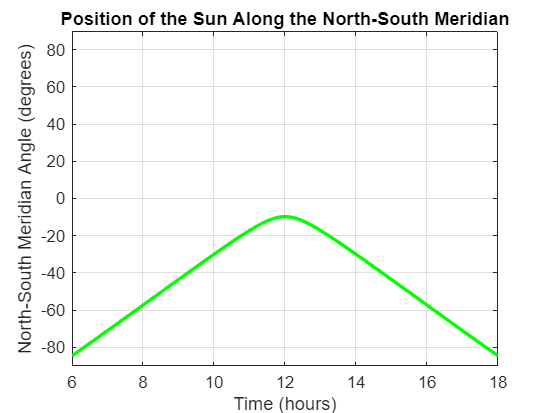

% Plot Sun's Trajectory on the North-South Meridian
figure;
plot(time, ns_meridian_angle, 'g', 'LineWidth', 2);
ylim([-90 90])
xlabel('Time (hours)');
ylabel('North-South Meridian Angle (degrees)');
title('Position of the Sun Along the North-South Meridian');
grid on;


disp('Calculation Complete!');

Calculation Complete!


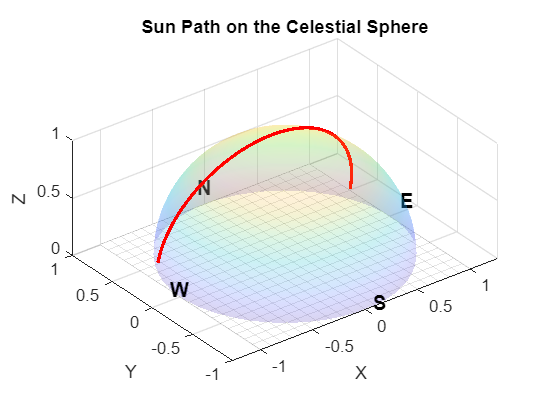

% Convert to Cartesian Coordinates for Celestial Sphere Plot
x = cos(deg2rad(altitude_deg)) .* sin(deg2rad(azimuth));
y = cos(deg2rad(altitude_deg)) .* cos(deg2rad(azimuth));
z = sin(deg2rad(altitude_deg));

% Plotting the results on a Celestial Sphere (Upper Half)
figure;
hold on;

% Plot the celestial sphere (a unit sphere)
[phi, theta] = meshgrid(linspace(0, pi/2, 100), linspace(0, 2*pi, 100));
x_sphere = sin(phi) .* cos(theta);
y_sphere = sin(phi) .* sin(theta);
z_sphere = cos(phi);
surf(x_sphere, y_sphere, z_sphere, 'FaceAlpha', 0.2, 'EdgeColor', 'none');


% Plot the Sun's position on the sphere for each time
plot3(x, y, z, 'r', 'LineWidth', 2);

% Plot N, S, E, W labels on the celestial sphere
text(1.1, 0, 0.1, 'E', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
text(-1.1, 0, 0.1, 'W', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
text(0, 1.1, 0.1, 'N', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
text(0, -1.1, 0.1, 'S', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');

% Plot the plane z = 0 (horizon)
[X, Y] = meshgrid(-1:0.1:1, -1:0.1:1);
Z = zeros(size(X));  % Horizon plane at z = 0
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeAlpha', 0.1);  % Horizon plane (white)

% Labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Sun Path on the Celestial Sphere');
grid on;
axis equal;
view(3);
hold off;